
clear vars; clc                           % Clear Previous Workspace

% Input Data and Options
airfoil_check = false;                    % Check Panels
airfoil_type = AirfoilType.NACA;         % 1: NACA 2: Excel
plot_stream = true;                     % Plot Stream Lines of Airfoil
regression = false;                       % Angle of Attack Vector must be at 4 elements for Regression
export_af = false;                        % Export Airfoil Extraploation to Excel
export_data = false;                     % Export Relevant Data to Excel
export_figures = false;

naca_name = '6814'; 
file_path = "C:\Users\asing\OneDrive\Documents\MATLAB\Vortex Panel Method\NACA 23012.xlsx";      % File Path for Excel File (Change for Different Files)

boundary_points = 50;                     % Number of Points for Analysis (Only used for NACA)



% Run Conditions

aoa_init = 0;
aoa_final = 10; % Final must be greater than or equal to initial
aoa_step = 1;
aoa_vector = aoa_init:aoa_step:aoa_final;

uniform_flow_velocity = 10; % Flow velocity assumed for calculations







% Airfoil Extrapolation
if airfoil_type == AirfoilType.NACA && strlength(naca_name) == 4

    [x_upper, y_upper, x_lower, y_lower, plot_title] = naca4(naca_name,boundary_points, export_af);

elseif airfoil_type == AirfoilType.NACA && strlength(naca_name) == 5

    [x_upper, y_upper, x_lower, y_lower, plot_title] = naca5(naca_name,boundary_points, export_af);

elseif airfoil_type == AirfoilType.Excel

    [x_upper, y_upper, x_lower, y_lower, plot_title] = extract_excel_data(file_path);
   
end



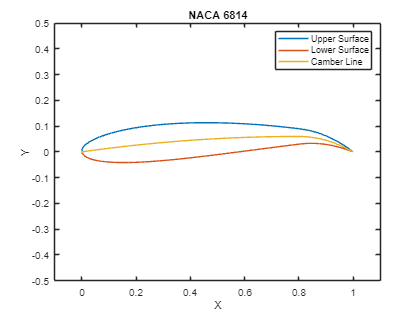


% Airfoil Plot
plot_airfoil(x_upper, y_upper, x_lower, y_lower, plot_title, export_figures); 


% Panel Generation
[x_boundary, y_boundary, x_control, y_control, delta, phi, beta, panel_lengths] = gen_panels(x_upper, y_upper, x_lower, y_lower, aoa_vector);




% Airfoil Panel Check

if airfoil_check

    check_airfoil(x_boundary, y_boundary, x_control, y_control, delta, panel_lengths, boundary_points, plot_title, export_figures); 

end



% Coefficent Calculation
[normal_coefficent_1, normal_coefficent_2, tangent_coefficent_1, tangent_coefficent_2] = calc_norm_tang_coefficents(x_control, y_control, x_boundary, y_boundary, phi, panel_lengths); 
    



% Solve Differential Equation with Kutta Condition and Pressure Distribution
[resultant_matrix, gamma, tangent_velocity, pressure_coefficient] = kutta_cp_system_solver(normal_coefficent_1, normal_coefficent_2, tangent_coefficent_1, tangent_coefficent_2, x_boundary, aoa_vector, beta, uniform_flow_velocity);



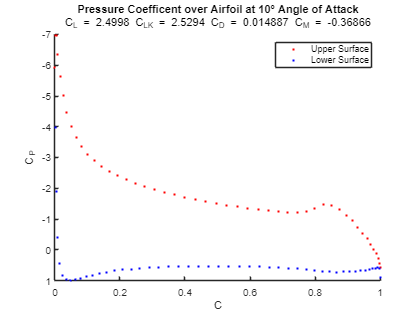

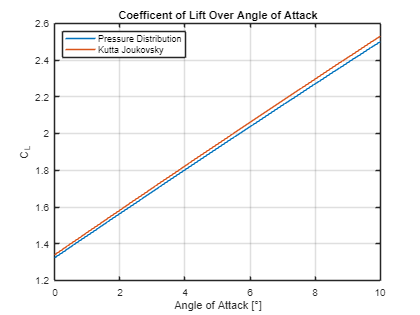

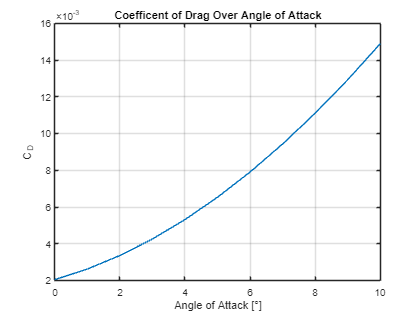

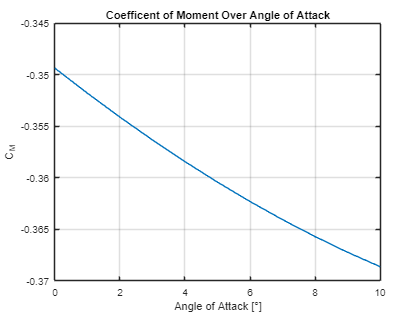


aoa_index = 10; % Do not use slider in regression mode, set index in normal mode and then run regression

% Plot Results of Analysis (Coefficient of Pressure, Coefficent(s) of Lift, Coefficent of Drag, Coefficent of Moment)
if regression

    [upper_model, lower_model, pressure_dist_model, kutta_model, drag_model, moment_model, export] = plot_results_regression(aoa_vector, x_control, pressure_coefficient, panel_lengths, y_control, gamma, delta, uniform_flow_velocity, aoa_index, export_data, plot_title, export_figures); %#ok<*UNRCH>

else
    
    plot_results(aoa_vector, x_control, pressure_coefficient, panel_lengths, y_control, gamma, delta, uniform_flow_velocity, aoa_index, export_data, plot_title, export_figures); 

end

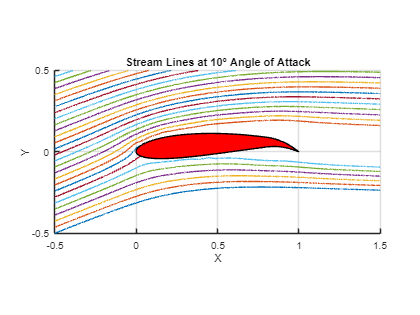


x_grid = 70;         % Controls Stream Line Contour Grids
y_grid = 70;

x_vals = [-0.5; 1.5]; % Plot Axes Limits
y_vals = [-0.5; 0.5];

stream_step = 0.01;  
max_vertices = x_grid * y_grid * 100;

stream_grid_percent = 40;  % Controls the Amount of Stream Lines Calculated and Plotted

if plot_stream

    plot_streamlines(x_grid, y_grid, x_vals, y_vals, stream_step, phi, max_vertices, panel_lengths, stream_grid_percent, x_boundary, y_boundary, uniform_flow_velocity, aoa_vector, gamma, aoa_index, export_figures, plot_title);

end


% Export Models
if regression && export

    export_model(upper_model, 'Output\' + plot_title + '_CP_Upper_Surface_Model.xlsx'); 

    export_model(lower_model, 'Output\' + plot_title + '_CP_Lower_Surface_Model.xlsx');

    export_model(pressure_dist_model, 'Output\' + plot_title + '_Pressure_Distribution_Lift_Model.xlsx');

    export_model(kutta_model,'Output\' + plot_title + '_Kutta_Lift_Model.xlsx');

    export_model(drag_model,'Output\' + plot_title + '_Drag_Model.xlsx');

    export_model(moment_model,'Output\' + plot_title + '_Moment_Model.xlsx');

end




